#  Load, register, segment and neuropil correct 2P data

## Path names

clear all
clear all global
close all

fn_base = 'Z:\\All_Staff'; %% sets base path to main directory in Isilon
Aging_pn = fullfile(fn_base, 'home\ACh\Aging');
data_fn = fullfile(Aging_pn, '\data\2p'); % creates pathanme to access 2P data in my folder
mworks_fn = fullfile(fn_base, 'Behavior\Data'); % creates pathname to access MWorks behavioral data from main directory
fnout = fullfile(Aging_pn, '\Gloria\neuralTCs'); % creates pathname to save analysis when complete

% TL;DR: the purpose of these functions are to set up paths for MATLAB to access the necessary files for running the script. 
% The reason why we use filename() rather than directly storing the path in the variable helps with transportability of the code between operating systems and users.

## Specific experiment information

date = '230331'; % string value indicating the current date (YYMMDD)
run = '001'; % string value indicating image folder (recording session from that day)
time = '1300'; % string value for current time (HHMM)
mouse = 'i2209'; % string value for mouse ID
frame_rate = 14.99; % float value for FPS
datemouse = [date '_' mouse];
datemouserun = [date '_' mouse '_' run];

## Load 2P data

Load mworks data (stimulus and behavior information)

fName = fullfile(mworks_fn, ['data-' mouse '-' date '-' time '.mat']);
load(fName);
% loads the appropriate MWorks file searching in the path specified earlier
% second argument in the function produces a string for the unique filename

Load 2P metadata

CD = fullfile(data_fn, mouse, date, run); % accesses appropriate file based on mouse ID, date, and session
cd(CD); % sets current working directory to CD, AKA this means that our directory is now the 2P folder instead of the MWorks folder?
imgMatFile = [run '_000_000.mat']; % accesses the actual MATLAB file
load(imgMatFile); % loads into MATLAB

Load 2P images

totframes = input.counterValues{end}(end); %this is from the mworks structure- finds the last value clocked for frame count
fprintf(['Reading ' num2str(totframes) ' frames \r\n']) % prints out a string saying how many total frames are read

Reading 57600 frames 


data = sbxread([run '_000_000'],0,totframes); % reads raw image data from frame 0 to the total frames

Data is nPMT x nYpix x nXpix x nframes. 

fprintf(['Data is ' num2str(size(data))]) % PMT means photo multiplier tube

Data is 1    529    796  57600

% prints out a string saying the sizes of each dimension in array "data."
% there are four dimensions in data, PMT, Y pixels, X pixels, and frames

When imaging a single channel, nPMT = 1, so squeeze:

data = squeeze(data);
% squeeze() compresses dimensions of the array "data" by removing
% dimensions of length 1, this removes the first dimension (nPMT)

## Register 2P data

Goal here is to remove X-Y movement artifacts

1. Find a stable target

    a. Plot average of 500 frames throughout stack

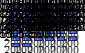

nframes = 500; %nframes to average
nskip = 1500; %nframes to skip for each average

nep = floor(size(data,3)./nskip); % number of stacks (averages) you have
[n n2] = subplotn(nep); % creates the plots of you need with nrows and ncolumns
figure('units','normalized','outerposition',[0 0 1 1]); % specifies units to be normalized and places the full window
for i = 1:nep; % index value loops through each stack, tells you what frames you're taking 
    subplot(n,n2,i); % divides figure into row x column grid, creates axes in position specified by stack
    imagesc(mean(data(:,:,1+((i-1)*nskip):nframes+((i-1)*nskip)),3)); % ???? plots data as an image where each values are the average; telling mean to take dimension (third one, time (z))
    title([num2str(1+((i-1)*nskip)) '-' num2str(nframes+((i-1)*nskip))]); % adds title to figure for frames plotted
end

    b. GUI to select target image- choose one that is sharp and close to center of stack

f=gcf; % chooses current figure
w = waitforbuttonpress; %click on subplot
if w == 0 % detects a click
    axesClicked = gca; % gca = current axes
    allAxes = flipud(findobj(f.Children,'Type','axes')); %rows flipped upside-down
    numClicked = find(axesClicked==allAxes);
    close all
    %purpose of this loop is to find all axes in the figure and find which one matches the
    %currently clicked axes
end
fprintf(['Selected subplot ' num2str(numClicked)])

Selected subplot 20

%prints which subplot you clicked

%criteria: sharpness and clearness, take a stable period to register
%everything
%take it towards the middle of the stack
% choose 500 frames that are stable, take an average
%images represent FOV

    c. Create target image

data_avg = mean(data(:,:,1+((numClicked-1)*nskip):nframes+((numClicked-1)*nskip)),3); %???

2. stackRegister minimizes the difference of each frame from the target

[out, data_reg] = stackRegister(data,data_avg);

Starting, frame 0
Frame 250 (9.9 fps)
Frame 500 (13.3 fps)
Frame 750 (15.0 fps)
Frame 1000 (16.1 fps)
Frame 1250 (16.8 fps)
Frame 1500 (17.3 fps)
Frame 1750 (17.6 fps)
Frame 2000 (17.9 fps)
Frame 2250 (18.2 fps)
Frame 2500 (18.4 fps)
Frame 2750 (18.5 fps)
Frame 3000 (18.6 fps)
Frame 3250 (18.8 fps)
Frame 3500 (18.8 fps)
Frame 3750 (18.9 fps)
Frame 4000 (19.0 fps)
Frame 4250 (19.1 fps)
Frame 4500 (19.1 fps)
Frame 4750 (19.2 fps)
Frame 5000 (19.3 fps)
Frame 5250 (19.3 fps)
Frame 5500 (19.3 fps)
Frame 5750 (19.4 fps)
Frame 6000 (19.4 fps)
Frame 6250 (19.4 fps)
Frame 6500 (19.5 fps)
Frame 6750 (19.5 fps)
Frame 7000 (19.5 fps)
Frame 7250 (19.5 fps)
Frame 7500 (19.6 fps)
Frame 7750 (19.6 fps)
Frame 8000 (19.6 fps)
Frame 8250 (19.6 fps)
Frame 8500 (19.6 fps)
Frame 8750 (19.7 fps)
Frame 9000 (19.7 fps)
Frame 9250 (19.7 fps)
Frame 9500 (19.7 fps)
Frame 9750 (19.7 fps)
Frame 10000 (19.7 fps)
Frame 10250 (19.7 fps)
Frame 10500 (19.8 fps)
Frame 10750 (19.8 fps)
Frame 11000 (19.8 fps)
Frame 11250 (

New average image after registration

data_reg_avg = mean(data_reg,3);

Save registration shifts and target, and mworks data

mkdir(fullfile(fnout, mouse, datemouse, datemouserun)) %creates new folder
save(fullfile(fnout, mouse, datemouse, datemouserun, [datemouserun '_reg_shifts.mat']), 'data_reg_avg', 'out', 'data_avg') % saves the registered shifts
save(fullfile(fnout, mouse, datemouse, datemouserun, [datemouserun '_input.mat']), 'input') %saves input

Test registration

    a. Make sure first and last images are sharp and similar. Focus on vasculature and nuclei- not cells since F changes

ind = [1 nep];
for i = 1:length(ind) 
    subplot(2,1,i); 
    ix = ind(i);
    imagesc(mean(data_reg(:,:,1+((ix-1)*nskip):nframes+((ix-1)*nskip)),3)); % ???
    title([num2str(1+((ix-1)*nskip)) '-' num2str(nframes+((ix-1)*nskip))]); % ???
end
print(fullfile(fnout, mouse, datemouse, datemouserun, [datemouserun '_FOV_first&last.pdf']), '-dpdf')

%check the registration when done, potentially the target can be choosen
%poorly and the registration will be bad
%with longer runs, it's good to compare between the beginning and end to
%make sure there's not a lot of drift - lock down the feet carefully, don't
%bump the wheels, evaporation of the liquid under the objective can change
%focal plane, good thick goopiness of the polymer

    b. Average of all frames should be sharp

imagesq(data_reg_avg); 
print(fullfile(fnout, mouse, datemouse, datemouserun, [datemouserun '_FOV_avg.pdf']), '-dpdf')
clear data

## Segment 2P data

Goal here is to create a cell mask to extract fluorescence timecourses

1. Find activated cells

    a. Reshape data stack to segregate trials 

    First need to know how many frames per trial and how many trials

nOn = input.nScansOn; %on trials
nOff = input.nScansOff; %off trials
ntrials = size(input.tGratingDirectionDeg,2); %this is a cell array with one value per trial, so length = ntrials
sz = size(data_reg); %length of each dimension from registration

        Each trial has nOff frames followed by nOn frames, so can reshape stack so nYpix x nXpix x nFrames/Trial (nOn+nOff) x nTrials

data_tr = reshape(data_reg,[sz(1), sz(2), nOn+nOff, ntrials]);
fprintf(['Size of data_tr is ' num2str(size(data_tr))])

Size of data_tr is 529  796   90  640

    b. Find baseline F from last half of off period- avoids decay of previous on trial

data_f = mean(data_tr(:,:,nOff/2:nOff,:),3); 

    c. Find dF/F for each trial

data_df = bsxfun(@minus, double(data_tr), data_f); 
data_dfof = bsxfun(@rdivide,data_df, data_f); 
clear data_f data_df data_tr

    d. Find average dF/F for each stimulus condition (this is for an experiment with changing grating direction)

Dir = celleqel2mat_padded(input.tGratingDirectionDeg); %transforms cell array into matrix (1 x ntrials)
Dirs = unique(Dir);
nDirs = length(Dirs);
data_dfof_avg = zeros(sz(1),sz(2),nDirs); %create empty matrix with FOV for each direction: nYpix x nXPix x nDir

nStim = nDirs;
[n n2] = subplotn(nDirs); %function to optimize subplot number/dimensions
for idir = 1:nDirs
    ind = find(Dir == Dirs(idir)); %find all trials with each direction
    data_dfof_avg(:,:,idir) = mean(mean(data_dfof(:,:,nOff+1:nOn+nOff,ind),3),4); %average all On frames and all trials
    subplot(n,n2,idir)
    imagesc(data_dfof_avg(:,:,idir))
end
clear data_dfof
% df/F by each stimulus condition so that we can get all of the neurons
% response to each stimulus condition and max across all stimulus

        Filtering data helps make cells more visible for selection

myfilter = fspecial('gaussian',[20 20], 0.5);
data_dfof_avg_all = imfilter(data_dfof_avg,myfilter);
data_dfof_max = max(data_dfof_avg_all,[],3); %finds all active cells by taking max projection

save(fullfile(fnout, mouse, datemouse, datemouserun, [datemouserun '_stimActFOV.mat']), 'data_dfof_max', 'data_dfof_avg_all', 'nStim')

    2. Create cell masks from active cells

        Concatenate images of max and all directions

data_dfof = cat(3,data_dfof_max, data_dfof_avg_all);

        Set up empty matrices for segmenting cells

mask_data = data_dfof;
mask_exp = zeros(sz(1),sz(2));
mask_all = zeros(sz(1), sz(2));

        a. Click on bright cells in mask to create mask- blue shading should fill bright region of single cell evenly.  

            If cell not filled well, press 'z' or shift+click to remove. Try again by 1) clicking on different spot- brighter spot will make fill smaller- if there are two cells also helps to fill brighter cell first; 2) change threshold- higher thresh will make fill smaller; 3) wait for different image where cell might be more distinct from background

            Press 'return' when done with each image. 

            Next images will have black spots where cells were previously selected- don't let new masks encroach on old cells or will fuse. imCellBuffer helps with this.

for iStim = 1:size(data_dfof,3)    
    mask_data_temp = mask_data(:,:,iStim);
    mask_data_temp(find(mask_exp >= 1)) = 0; %blacks out old cells
    bwout = imCellEditInteractiveLG(mask_data_temp); %selection GUI
    mask_all = mask_all+bwout; %adds new cells to old cells
    mask_exp = imCellBuffer(mask_all,3)+mask_all; %creates buffer around cells to avoid fusing
    close all
end

** Cannot undo: no cells added yet
** Cannot undo: no cells added yet



%across images, the algorithim doesnt have memory of overlapping cells
% this buffer functions is added so that between images they don't touch
% why cant they touch? the image produced is all 0 and 1s, bwlabel, turns
% all local pixels touchinf each other into a number
% if they're touching, the function won't register it as separate cells

        b. Number independent regions for mask

mask_cell = bwlabel(mask_all); %turns logical into numbered cells
figure;
imagesc(mask_cell)

        c. Create neuropil masks (these are regions around each cell without overlap from neighboring cells)

nMaskPix = 5; %thickness of neuropil ring in pixels
nBuffPix = 3; %thickness of buffer between cell and ring
mask_np = imCellNeuropil(mask_cell,nBuffPix,nMaskPix);

% the whole purpose of this is to get timecourse of these cells rather than
% a bunch of pixels
save(fullfile(fnout, mouse, datemouse, datemouserun, [datemouserun '_mask_cell.mat']), 'data_dfof_max', 'mask_cell', 'mask_np')
clear data_dfof data_dfof_avg max_dfof mask_data mask_all mask_2 data_base data_base_dfof data_targ data_targ_dfof data_f data_base2 data_base2_dfof data_dfof_dir_all data_dfof_max data_dfof_targ data_avg data_dfof2_dir data_dfof_dir 

## Neuropil subtraction

Goal is to remove contamination from out-of-focus fluorescence

- Extract cell timecourses

data_tc = stackGetTimeCourses(data_reg, mask_cell); %applies mask to stack to get timecourses

            Timecourses are nFrames x nCells

fprintf(['data_tc is ' num2str(size(data_tc))]) 
nCells = size(data_tc,2);

            Downsampled timecourses for neuropil subtraction- averageing decreases noise

down = 5; %number of frames to average
data_reg_down = stackGroupProject(data_reg,down); %averages every 5 frames in stack  
data_tc_down = stackGetTimeCourses(data_reg_down, mask_cell);   
% takes an average for all these pixels for these frames
% output of this is data_tc
% it's called neuropil because it's coming from axons and dendrites from
% neighboring cells
% problem is that if you have neurons that are contributing to the signals
% in the cell you're recording, it'll make the tuning since more broad, can
% give more synchrousnous activity
% this is a SCALED subtraction

        2.  Extract neuropil timecourses (full and downsampled)

sz = size(data_reg);
np_tc = zeros(sz(3),nCells);
np_tc_down = zeros(floor(sz(3)./down), nCells);
for i = 1:nCells
     np_tc(:,i) = stackGetTimeCourses(data_reg,mask_np(:,:,i));
     np_tc_down(:,i) = stackGetTimeCourses(data_reg_down,mask_np(:,:,i));
     fprintf(['Cell #' num2str(i) '%s\n']) 
end

        3. Find best neuropil weights by maximizing skew on downsampled subtractions

            Assumes calcium signals are 1) sparse and 2) positive.  Too little subtraction will decrease sparseness and too much will make signals negative. Thus, the best neuropil subtraction should yield the highest skew.

        a. Measure skew for all weights:

ii= 0.01:0.01:1;
x = zeros(length(ii), nCells);
for i = 1:100
    x(i,:) = skewness(data_tc_down-tcRemoveDC(np_tc_down*ii(i)));
end
% the more skewed the distribution, the more representative it is,
% spareness is good
% want to maximize this enough to subtract off enough skewness
% moves through each fraction and finds which one gives the most skews

        b. Find index with highest skew for each cell

[max_skew ind] =  max(x,[],1); 

        c. convert to weight

np_w = 0.01*ind; 

        4. Subtract weighted neuropil response from full timecourses

npSub_tc = data_tc-bsxfun(@times,tcRemoveDC(np_tc),np_w);
clear data_reg data_reg_down

save(fullfile(fnout, mouse, datemouse, datemouserun, [datemouserun '_TCs.mat']), 'data_tc', 'np_tc', 'npSub_tc')
% how to control signal to noise in data collection? density of flurophore,
% for deeper imaging, (L4/L5) transgenic line that selectively expresses
% something only in those layers and prevents fluoresence from superficial
% layers
% second option: improving your optics
% point spread function of the optical setup (x y is better than z
% resolution)
% point spread function is controlled by numerical aperature 
% higher numerical aperature = better sectioning, but clunkier
% good sectioning, a lot of motion